% PROBLEM 2-A

% Clear workspace
close all
clear
clc

% Add parser and solver to path
addpath(genpath('C:\Users\tsamak\Downloads\MathWorks\Toolboxes\archives\required\YALMIP'))
addpath(genpath('C:\Users\tsamak\Downloads\MathWorks\Toolboxes\archives\required\SeDuMi'))

% Define the system matrices A, B, and C
A = [-1.01887 0.90506; 0.82225 -1.07741];
B = [0.00203; -0.00164];
C = [15.87875, 1.48113];
D = 0;

% Define the LMI variables
P = sdpvar(2, 2);
Gamma_ep = sdpvar(1, 1);

% Define the LMI constraints
LMI1 = [-Gamma_ep*eye(1), C*P*C'; C*P*C', -eye(1)] <= 0;
LMI2 = A*P+P*A'+B*B' <= 0;
LMI3 = -P <= 0;

% Set up the objective
Objective = Gamma_ep;

% Define the solver settings (use an LMI solver like YALMIP with a solver of your choice)
options = sdpsettings('verbose', 1, 'solver', 'sedumi');

% Solve the LMI problem
solution = optimize([LMI1, LMI2, LMI3], Objective, options);

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 4, order n = 7, dim = 13, blocks = 4
nnz(A) = 14 + 0, nnz(ADA) = 16, nnz(L) = 10
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            7.94E+00 0.000
  1 :  -4.73E-02 6.45E-01 0.000 0.0813 0.9900 0.9900   1.67  1  1  1.4E+00
  2 :  -7.96E-03 1.27E-01 0.000 0.1966 0.9000 0.9000   1.08  1  1  9.5E-01
  3 :  -3.94E-05 3.12E-04 0.000 0.0025 0.9990 0.9990   1.02  1  1  8.5E-02
  4 :  -9.90E-06 9.69E-05 0.000 0.3110 0.9000 0.9000   1.57  1  1  1.5E-02
  5 :  -2.87E-06 3.26E-05 0.000 0.3366 0.9000 0.9000   1.45  1  1  3.4E-03
  6 :  -9.54E-07 1.08E-05 0.000 0.3299 0.9000 0.9000   1.30  1  1  8.4E-04
  7 :  -3.67E-07 3.41E-06 0.000 0.3169 0.9000 0.9000   1.19  1  1  2.2E-04
  8 :  -1.71E-07 1.01E-06 0.000 0.2947 0.9000 0.9000   1.11  1  1  6.0E-05
  9 :  -1.04E-07 2.35E-07 0.000 0.2340 0.9000 0.9000   1.06  1  1  1.3E-05
 10 :  -8.87E-08 5.0


if solution.problem == 0
    % Extract the optimal solution
    optimal_Gamma_ep = value(Gamma_ep)^(0.25);
    % Display the result
    fprintf('Energy-to-Peak Gain (Gamma_ep): %.4f\n', optimal_Gamma_ep);
else
    fprintf('LMI problem could not be solved.\n');
end

Energy-to-Peak Gain (Gamma_ep): 0.0172


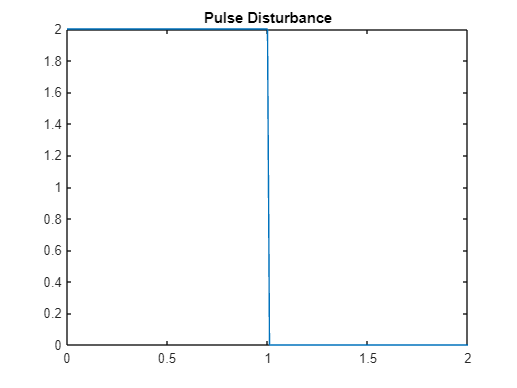

% PROBLEM 2-B

% Define the state-space system
A = [-1.01887 0.90506; 0.82225 -1.07741];
B = [0.00203; -0.00164];
C = [15.87875 1.48113];
D = 0;

% Define the disturbance signal w_g(t)
t = 0:0.01:2;  % Time vector from 0 to 2 with a step size of 0.01
w_g = 2 * (t >= 0 & t <= 1);  % Pulse disturbance, 2 for 0 ≤ t ≤ 1, 0 otherwise
plot(t,w_g)
title('Pulse Disturbance')


% Calculate the L2-norm (energy) of the disturbance signal
energy_L2 = sqrt(trapz(t, w_g.^2));
disp(['Energy of the disturbance signal: ', num2str(energy_L2)]);

Energy of the disturbance signal: 2.005



% Simulate the system response
sys = ss(A, B, C, D);
[y, t, x] = lsim(sys, w_g, t);

% Estimate the energy of the response to a pulse disturbance
energy_response = sqrt(trapz(t, y.^2)); % L2 norm

fprintf('Estimated energy of system response: %f\n', energy_response);

Estimated energy of system response: 0.026694



if optimal_Gamma_ep >= energy_response
    fprintf('System response is consistent with Gamma_ep.\n');
else
    fprintf('System response is not consistent with Gamma_ep.\n');
end

System response is not consistent with Gamma_ep.


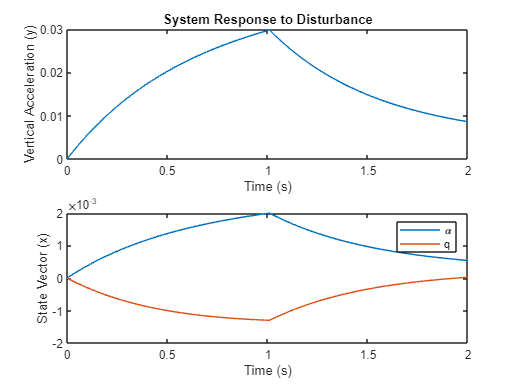


% Plot the response
subplot(2, 1, 1);
plot(t, y);
xlabel('Time (s)');
ylabel('Vertical Acceleration (y)');
title('System Response to Disturbance');

subplot(2, 1, 2);
plot(t, x);
xlabel('Time (s)');
ylabel('State Vector (x)');
legend('\alpha', 'q');

% PROBLEM 2-C

% Define the system matrices A, B, and C
A = [-1.01887 0.90506; 0.82225 -1.07741];
B = [0.00203; -0.00164];
C = [15.87875, 1.48113];
D = 0;

% Define the LMI variables
P = sdpvar(2, 2);
Gamma_ee = sdpvar(1, 1);

% Define the LMI constraints
LMI = [A'*P + P*A, P*B, C'; B'*P, -Gamma_ee*eye(1), D'; C, D, -Gamma_ee*eye(1)] <= 0;

% Set up the objective
Objective = Gamma_ee;

% Define the solver settings (use an LMI solver like YALMIP with a solver of your choice)
options = sdpsettings('verbose', 1, 'solver', 'sedumi');

% Solve the LMI problem
solution = optimize(LMI, Objective, options);

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 4, order n = 5, dim = 17, blocks = 2
nnz(A) = 13 + 0, nnz(ADA) = 16, nnz(L) = 10
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.69E+01 0.000
  1 :  -1.56E+01 3.67E+00 0.000 0.2168 0.9000 0.9000   0.88  1  1  2.2E+00
  2 :  -7.55E+00 8.11E-01 0.000 0.2213 0.9000 0.9000   1.28  1  1  5.0E-01
  3 :  -3.97E+00 1.94E-01 0.000 0.2385 0.9000 0.9000   0.72  1  1  1.4E-01
  4 :  -2.01E+00 4.18E-02 0.000 0.2159 0.9000 0.9000   0.44  1  1  3.6E-02
  5 :  -1.06E+00 9.17E-03 0.000 0.2196 0.9000 0.9000   0.36  1  1  1.2E-02
  6 :  -6.28E-01 2.22E-03 0.000 0.2424 0.9000 0.9000   0.38  1  1  4.3E-03
  7 :  -4.25E-01 6.37E-04 0.000 0.2863 0.9000 0.9000   0.43  1  1  1.7E-03
  8 :  -2.71E-01 1.72E-04 0.000 0.2695 0.9000 0.9000   0.41  1  1  7.1E-04
  9 :  -1.80E-01 4.77E-05 0.000 0.2781 0.9000 0.9000   0.44  1  1  2.9E-04
 10 :  -1.18E-01 1.4


if solution.problem == 0
    % Extract the optimal solution
    optimal_Gamma_ee = value(Gamma_ee);
    
    % Estimate the energy of the response to a pulse disturbance (adjust the time horizon as needed)
    T = 10; % Adjust the time horizon as needed
    sys = ss(A, B, C, 0);
    t = 0:0.01:T;
    [y, t] = lsim(sys, ones(size(t)), t); % Pulse disturbance input is ones
    
    energy_response = sqrt(trapz(t, y.^2)); % L2 norm
    
    fprintf('Energy-to-Energy Gain (Gamma_ee): %f\n', optimal_Gamma_ee);
    fprintf('Estimated energy of system response: %f\n', energy_response);
    
    if optimal_Gamma_ee >= energy_response
        fprintf('System response is consistent with Gamma_ee.\n');
    else
        fprintf('System response is not consistent with Gamma_ee.\n');
    end
else
    fprintf('LMI problem could not be solved.\n');
end

Energy-to-Energy Gain (Gamma_ee): 0.031559


Estimated energy of system response: 0.074341


System response is not consistent with Gamma_ee.


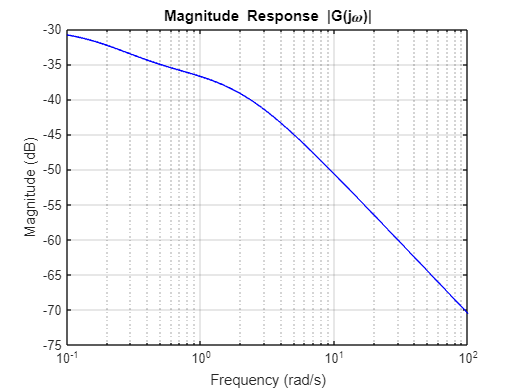

% PROBLEM 2-D

% Define the state-space system
A = [-1.01887 0.90506; 0.82225 -1.07741];
B = [0.00203; -0.00164];
C = [15.87875 1.48113];
D = 0;
sys = ss(A, B, C, D);

% Define a range of frequencies
omega = logspace(-1, 2, 100);  % Adjust the frequency range as needed

% Calculate the frequency response of the system
[mag, ~, ~] = bode(sys, omega);

% Extract the magnitude for the SISO system
mag_siso = squeeze(mag);

% Find the peak magnitude and its corresponding frequency
[max_mag, idx] = max(mag_siso);
peak_freq = omega(idx);

% Plot the magnitude response
figure;
semilogx(omega, 20*log10(mag_siso), 'b');  % Plot in decibels
title('Magnitude Response |G(j\omega)|');
xlabel('Frequency (rad/s)');
ylabel('Magnitude (dB)');
grid on;


% Display the peak magnitude and frequency
fprintf('Peak Magnitude (dB): %.4f dB at Frequency %.4f rad/s\n', 20*log10(max_mag), peak_freq);

Peak Magnitude (dB): -30.8437 dB at Frequency 0.1000 rad/s


fprintf('Energy-to-Energy Gain (Gamma_ee): %.4f\n', max_mag);

Energy-to-Energy Gain (Gamma_ee): 0.0287



if abs(optimal_Gamma_ee-max_mag) <= 0.01
    fprintf('Peak is equivalent to Gamma_ee.\n');
else
    fprintf('Peak is not equivalent to Gamma_ee.\n');
end

Peak is equivalent to Gamma_ee.
